# Code commenting

A colleague has recently left your development team at work. They were a great coder, but notoriously bad at commenting their work. Your boss has asked you to go through one of their scripts which contains some work on classifying hand-written letter shapes, and add comments that will help the rest of your team understand what's going on. You should add comments in your own words and you should prioritise clearly explaining what is going on to colleagues who may not have much experience of Machine Learning. It's fine if your comments go over more than one line.

The steps you should comment on, and the number of marks available for each comment are indicated below:

% read the letterdata dataset:
clear all;
data = readtable('letterdata.csv');

% re-seed Matlab's random number generator:
rng(1);

% shuffle the data and create a testing dataset and a training dataset:.
data_shuffled = data(randperm(size(data,1)), :);

% add your comment here [2 marks]: ...
data_test = data_shuffled(1:1:16000, :);
data_train = data_shuffled(16001:1:end, :);

% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test{:,'letter'});
test_examples = data_test;
test_examples(:,'letter') = [];

% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train{:,'letter'});
train_examples = data_train;
train_examples(:,'letter') = [];

% the code will print out all of the properties of m
% training a classifier from the training data
% train_examples - our table of training examples
% train_labels - our categorical array of associated class labels
m = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off')

m =   ClassificationTree
           PredictorNames: {'xbox'  'ybox'  'width'  'height'  'onpix'  'xbar'  'ybar'  'x2bar'  'y2bar'  'xybar'  'x2ybar'  'xy2bar'  'xedge'  'xedgey'  'yedge'  'yedgex'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [A    B    C    D    E    F    G    H    I    J    K    L    M    N    O    P    Q    R    S    T    U    V    W    X    Y    Z]
           ScoreTransform: 'none'
          NumObservations: 4000


  Properties, Methods



% use 'm' our trained classifier to classify the testing data(testing examples):
predictions = predict(m, test_examples);

% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =    544     5     0     1     1     1     2     7     0     0    11     6     6     0     3     0     1     3    20     1    16     0     0     5     2     0
     2   432     6    29     7    22    12    19    10     8    13     1     0     0     1     2     4    16    11     1     0     8     1     4     1     0
     0     3   435     0    12    10    23     2     2     0    11     5     1     0    11     0    10     5    10    14    11     0     1     1     0     1
     1    33     1   472     2     8     7    14     6     5     2     0     1    13    25    10     0     8    16     0     0     0     0     9     0     7
     8    16    21     1   455     5    18     0     2     4    10     7     0     0     0     0    11     5    17     1     0     2     1    12     1    23
     2    11     5     2     2   447     6     7     1     4     0     6     0     3     0    43     3     0    17    18     0    15     1     8     8     5
     3    19    18    14    21     2   431     3     0

order = 26×1 categorical array
     A 
     B 
     C 
     D 
     E 
     F 
     G 
     H 
     I 
     J 
     K 
     L 
     M 
     N 
     O 
     P 
     Q 
     R 
     S 
     T 
     U 
     V 
     W 
     X 
     Y 
     Z 



% calculate the overall classification accuracy of all the testing examples: 
p = sum(diag(c)) / sum(c(:))

p = 0.7469


% c_errors is a copy of the confusion matrix 
c_errors = c

c_errors =    544     5     0     1     1     1     2     7     0     0    11     6     6     0     3     0     1     3    20     1    16     0     0     5     2     0
     2   432     6    29     7    22    12    19    10     8    13     1     0     0     1     2     4    16    11     1     0     8     1     4     1     0
     0     3   435     0    12    10    23     2     2     0    11     5     1     0    11     0    10     5    10    14    11     0     1     1     0     1
     1    33     1   472     2     8     7    14     6     5     2     0     1    13    25    10     0     8    16     0     0     0     0     9     0     7
     8    16    21     1   455     5    18     0     2     4    10     7     0     0     0     0    11     5    17     1     0     2     1    12     1    23
     2    11     5     2     2   447     6     7     1     4     0     6     0     3     0    43     3     0    17    18     0    15     1     8     8     5
     3    19    18    14    21     2   431     

% changes all of the values around the diagonal line to zero(0) and keepes
% the orginal values plotted down the diagonal line going through the matrix
diag(diag(c_errors))

ans =    544     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   432     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   435     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   472     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   455     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0   447     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0   431     0    

% this code minuses the c_errors matrix from the diag(c_errors matrix)
c_errors = c_errors - diag(diag(c_errors))

c_errors =      0     5     0     1     1     1     2     7     0     0    11     6     6     0     3     0     1     3    20     1    16     0     0     5     2     0
     2     0     6    29     7    22    12    19    10     8    13     1     0     0     1     2     4    16    11     1     0     8     1     4     1     0
     0     3     0     0    12    10    23     2     2     0    11     5     1     0    11     0    10     5    10    14    11     0     1     1     0     1
     1    33     1     0     2     8     7    14     6     5     2     0     1    13    25    10     0     8    16     0     0     0     0     9     0     7
     8    16    21     1     0     5    18     0     2     4    10     7     0     0     0     0    11     5    17     1     0     2     1    12     1    23
     2    11     5     2     2     0     6     7     1     4     0     6     0     3     0    43     3     0    17    18     0    15     1     8     8     5
     3    19    18    14    21     2     0     

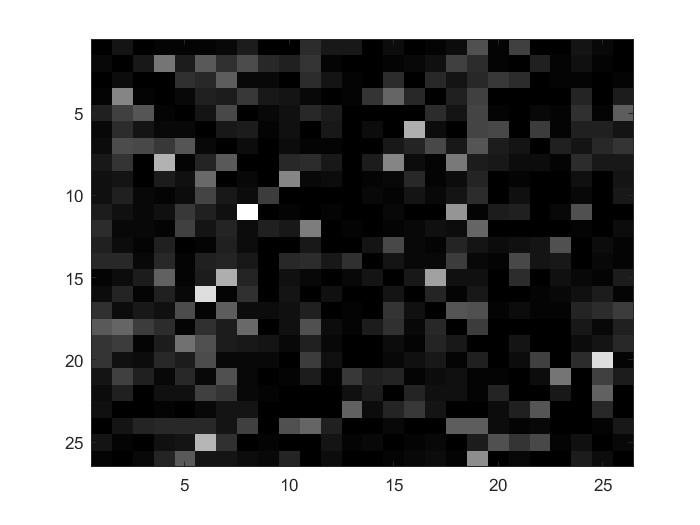

% create a colormap diagram that determnies wether there is an erro with
% the matrix the darker the color means that theres an error, however the
% lighter color mean that value is not an error
figure;
colormap('gray');
imagesc(c_errors)

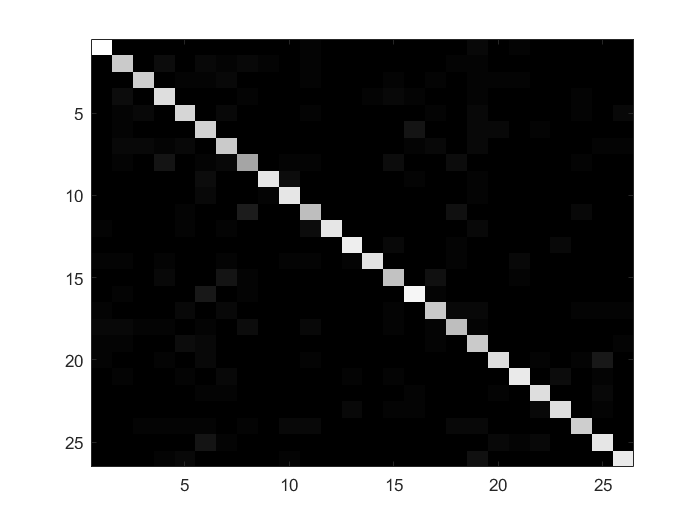

% this test shows the the larger numbers within the matrix are displayed a
% a bright white square and the black and dark sqaures surrounding are
% lower numbers within the matrix
figure;
colormap('gray');
imagesc(c)


% converts the matrix into an array
c_errors(:)

ans =      0
     2
     0
     1
     8
     2
     3
     6
     4
     4


% gives the index of the maximum value with the array
[~, m] = max(c_errors(:));
% ind2sub ----> determines the equivalent subscript values corresponding to a single index into an array
% returns the matricies [I,J] containing the equivalent row and column subscripts corresponding to each linear index in the matrix
[i,j] = ind2sub(size(c_errors), m);
% writes data to a text file and sorts the array elements I and J.
fprintf('%s mistaken for %s\n', order(i), order(j));

K mistaken for H


[Total: 20 marks]